fileName = 'dataset/CellRetention.xlsx';
filePath = fullfile(fileName);
sheets = sheetnames(filePath);

Gray = [0.75 0.75 0.75];
Lime = [0.2 0.8 0.2];
Gold = [1 0.8 0];
Chocolate = [0.8 0.4 0.1];
Steel = [0.3 0.5 0.7];
Salmon = [1 0.5 0.4];
Voilet = [0.9 0.5 0.9];

batteryID = '13';
batteryName = sprintf('cell%s', batteryID);
capacityData = readmatrix(filePath,'Sheet',batteryName);

cycle_full = capacityData(:,1)';
capacity_full = capacityData(:,2)'/100;

% Result files for predictions and baseline LSTM
resultfile = sprintf('test_results/%s_result.xlsx', batteryName)

resultfile = 'test_results/cell13_result.xlsx'

sheetNames = sheetnames(resultfile);
cycleSheets = sheetNames(startsWith(sheetNames, 'cycle'));

% Prediction evaluation ranges and labels
predRanges = [25, 50, 100];
rangeLabels = {'25', '50', '100', 'Full'};
predictorNames = {'LSTM', 'Hybrid', 'Compared'};

errorResults = {};
rulResults = {};

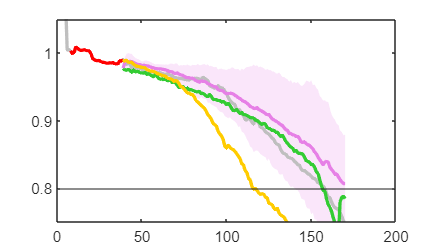

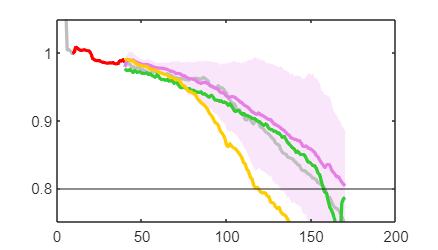

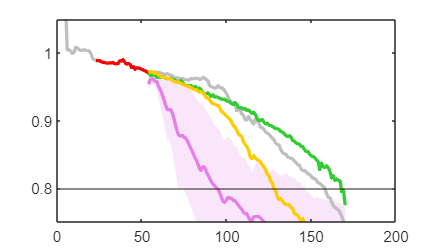

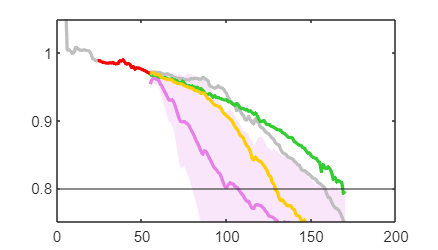

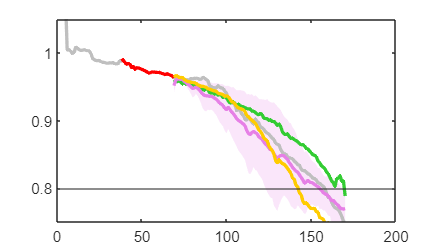

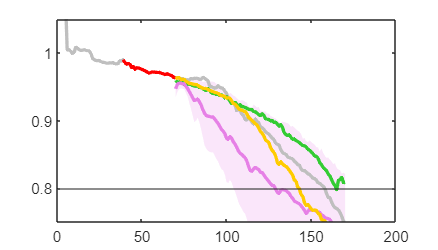

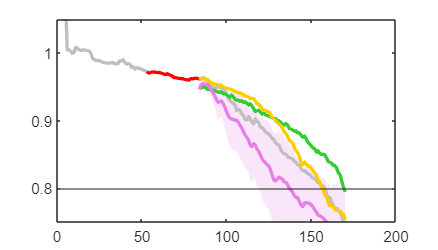

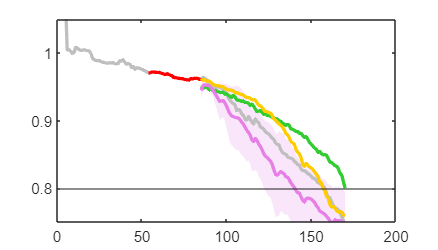

% Loop over each cycle sheet (each starting prediction point)
for i = 1:length(cycleSheets)
    sheetName = cycleSheets{i};
    % Read data from result file and baseline file
    data = readmatrix(resultfile, 'Sheet', sheetName);
    
    cycle = data(:,1)';
    trueCap = data(:,2)';
    LSTMPred = data(:,3)';
    hybridPred = data(:,4)';
    comparedPred = data(:,5)';
    hybridLower = data(:,7)';
    hybridUpper = data(:,8)';

    % Historical capacity fragment before the prediction start
    cycle_frag = cycle(1)-32+1 : cycle(1);
    capacity_frag = capacity_full(cycle_frag);

    % ------------------- Plotting -------------------
    figure('Position', [100, 100, 350, 200]);
    % Fill uncertainty band for Hybrid predictions
    fill([cycle, fliplr(cycle)], [hybridLower, fliplr(hybridUpper)], ...
         Voilet, 'FaceAlpha', 0.2, 'EdgeColor', 'none');
    hold on;
    
    plot(cycle_full, capacity_full, 'Color', Gray, 'LineWidth', 2);
    plot(cycle_frag, capacity_frag, 'Color', 'r', 'LineWidth', 2);
    plot(cycle, LSTMPred, 'Color', Lime, 'LineWidth', 2);
    plot(cycle, hybridPred, 'Color', Voilet, 'LineWidth', 2);
    plot(cycle, comparedPred, 'Color', Gold, 'LineWidth', 2);

%     title(sprintf('Cycle %s', extractAfter(sheetName, 'cycle')), 'Interpreter','none');
%     xlabel('Cycle');
%     ylabel('Capacity');
    hold off;
    yline(0.8)
    xlim([0 200]);
    ylim([0.75 1.05]);
    
    % ------------------- Error and RUL Computation -------------------
    nAvail = length(cycle);
    
    % Actual remaining useful life (RUL): index where true capacity first <= 0.8
    actualEolIdx = find(trueCap <= 0.8, 1, 'first');
    if isempty(actualEolIdx)
        actualRUL = NaN;
    else
        actualRUL = actualEolIdx;
    end
    
    % Collect predictions from all methods
    predictions = struct();
    predictions.LSTM = LSTMPred;
    predictions.Hybrid = hybridPred;
    predictions.Compared = comparedPred;
    
    predRUL = struct();
    for p = 1:length(predictorNames)
        predName = predictorNames{p};
        predVals = predictions.(predName);
        predEolIdx = find(predVals <= 0.8, 1, 'first');
        if isempty(predEolIdx)
            predRUL.(predName) = NaN;
        else
            predRUL.(predName) = predEolIdx;
        end
    end
    
    % Store RUL results in table format
    rulResults{end+1, 1} = batteryName;
    rulResults{end, 2} = sheetName;
    rulResults{end, 3} = cycle(1);
    rulResults{end, 4} = actualRUL;
    rulResults{end, 5} = predRUL.LSTM;
    rulResults{end, 6} = predRUL.Hybrid;
    rulResults{end, 7} = predRUL.Compared;

    for p = 1:length(predictorNames)
        predName = predictorNames{p};
        predVals = predictions.(predName);
        
        for r = 1:length(rangeLabels)
            rangeLabel = rangeLabels{r};
            
            if strcmp(rangeLabel, 'Full')
                if isnan(actualRUL) || nAvail < actualRUL
                    continue;
                else
                    evalLen = actualRUL;
                end
            else
                reqLen = predRanges(r);
                if isnan(actualRUL) || actualRUL < reqLen || nAvail < reqLen
                    continue;
                else
                    evalLen = reqLen;
                end
            end
            
            % Compute error metrics over the evaluation length
            trueSeg = trueCap(1:evalLen);
            predSeg = predVals(1:evalLen);
            errors = trueSeg - predSeg;
            absErrors = abs(errors);
            
            rmse = sqrt(mean(errors.^2)) * 100;
            mae = mean(absErrors) * 100;
            maxAE = max(absErrors) * 100;
            
            % Store error results
            errorResults{end+1, 1} = batteryName;
            errorResults{end, 2} = sheetName;
            errorResults{end, 3} = cycle(1);
            errorResults{end, 4} = predName;
            errorResults{end, 5} = rangeLabel;
            errorResults{end, 6} = evalLen;
            errorResults{end, 7} = rmse;
            errorResults{end, 8} = mae;
            errorResults{end, 9} = maxAE;
        end
    end
end

% Convert cell arrays to tables with appropriate variable names
errorTable = cell2table(errorResults, ...
    'VariableNames', {'Battery', 'Sheet', 'StartCycle', 'Predictor', ...
                      'Range', 'ActualLength', 'RMSE', 'MAE', 'MaxAE'});

rulTable = cell2table(rulResults, ...
    'VariableNames', {'Battery', 'Sheet', 'StartCycle', 'Actual_RUL', ...
                      'LSTM_RUL', 'Hybrid_RUL', 'Compared_RUL'});

% Display RUL prediction results
disp('========== RUL Prediction Results ==========');

========== RUL Prediction Results ==========


disp(rulTable);

     Battery          Sheet        StartCycle    Actual_RUL    LSTM_RUL    Hybrid_RUL    Compared_RUL
    __________    _____________    __________    __________    ________    __________    ____________

    {'cell13'}    {'cycle_039'}        39           121          119          NaN             78     
    {'cell13'}    {'cycle_040'}        40           120          119          NaN             80     
    {'cell13'}    {'cycle_054'}        54           106          115           42             75     
    {'cell13'}    {'cycle_055'}        55           105          115           53             75     
    {'cell13'}    {'cycle_069'}        69            91          102           87             75     
    {'cell13'}    {'cycle_070'}        70            90           96           60             74     
    {'cell13'}    {'cycle_084'}        84            76           87           55             74     
    {'cell13'}    {'cycle_085'}        85            75          NaN           57

disp('========== Error Metrics (Full range evaluated up to actual EOL = 0.8) ==========');

========== Error Metrics (Full range evaluated up to actual EOL = 0.8) ==========


disp(errorTable);

     Battery          Sheet        StartCycle     Predictor       Range      ActualLength      RMSE        MAE        MaxAE  
    __________    _____________    __________    ____________    ________    ____________    ________    ________    ________

    {'cell13'}    {'cycle_039'}        39        {'LSTM'    }    {'25'  }         25          0.70045     0.63885      1.2778
    {'cell13'}    {'cycle_039'}        39        {'LSTM'    }    {'50'  }         50           1.2019      1.0422      2.4415
    {'cell13'}    {'cycle_039'}        39        {'LSTM'    }    {'100' }        100           1.2849      1.1071      2.5291
    {'cell13'}    {'cycle_039'}        39        {'LSTM'    }    {'Full'}        121           1.3443      1.1708      2.5291
    {'cell13'}    {'cycle_039'}        39        {'Hybrid'  }    {'25'  }         25          0.68595     0.64086      1.2253
    {'cell13'}    {'cycle_039'}        39        {'Hybrid'  }    {'50'  }         50          0.59414     0.54595    


% Compute absolute errors for RUL predictions
rulErrorTable = rulTable;
rulErrorTable.LSTM_AE = abs(rulTable.Actual_RUL - rulTable.LSTM_RUL);
rulErrorTable.Hybrid_AE = abs(rulTable.Actual_RUL - rulTable.Hybrid_RUL);
rulErrorTable.Compared_AE = abs(rulTable.Actual_RUL - rulTable.Compared_RUL);

% Export results to Excel file
outputFile = sprintf('test_results/%s_AnalysisResults.xlsx', batteryName);
writetable(rulTable, outputFile, 'Sheet', 'RUL_Predictions');
writetable(rulErrorTable, outputFile, 'Sheet', 'RUL_Errors');
writetable(errorTable, outputFile, 'Sheet', 'ErrorMetrics');

fprintf('\nAnalysis completed! Results saved to: %s\n', outputFile);


Analysis completed! Results saved to: test_results/cell13_AnalysisResults.xlsx


fprintf('Included worksheets:\n');

Included worksheets:


fprintf('1. RUL_Predictions: Actual RUL and predicted RUL from each predictor\n');

1. RUL_Predictions: Actual RUL and predicted RUL from each predictor


fprintf('2. RUL_Errors: Absolute errors of RUL predictions\n');

2. RUL_Errors: Absolute errors of RUL predictions


fprintf('3. ErrorMetrics: RMSE/MAE/MaxAE for different prediction horizons\n');

3. ErrorMetrics: RMSE/MAE/MaxAE for different prediction horizons


% Summarize the number of evaluations, RMSE and MaxAE mean/variance for each prediction horizon
fprintf('\n========== Prediction Horizon Statistics Summary ==========\n');


========== Prediction Horizon Statistics Summary ==========


% Extract error data for this battery
batteryErrorData = errorTable(strcmp(errorTable.Battery, batteryName), :);

% Group statistics by predictor and range
predictorList = unique(batteryErrorData.Predictor);
rangeList = {'25', '50', '100', 'Full'};

statsResults = {};

for p = 1:length(predictorList)
    predName = predictorList{p};
    predData = batteryErrorData(strcmp(batteryErrorData.Predictor, predName), :);
    
    fprintf('\n--- %s ---\n', predName);
    
    for r = 1:length(rangeList)
        rangeName = rangeList{r};
        rangeData = predData(strcmp(predData.Range, rangeName), :);
        
        count = height(rangeData);
        
        if count > 0
            rmseMean = mean(rangeData.RMSE);
            rmseStd = std(rangeData.RMSE);
            maxAEMean = mean(rangeData.MaxAE);
            maxAEStd = std(rangeData.MaxAE);
            
            fprintf('%s horizon: %d evaluations | RMSE: %.3f±%.3f | MaxAE: %.3f±%.3f\n', ...
                rangeName, count, rmseMean, sqrt(rmseStd), maxAEMean, sqrt(maxAEStd));
        else
            rmseMean = NaN; rmseStd = NaN;
            maxAEMean = NaN; maxAEStd = NaN;
            fprintf('%s horizon: No valid data\n', rangeName);
        end
        
        % Store results
        statsResults{end+1, 1} = batteryName;
        statsResults{end, 2} = predName;
        statsResults{end, 3} = rangeName;
        statsResults{end, 4} = count;
        statsResults{end, 5} = rmseMean;
        statsResults{end, 6} = rmseStd;
        statsResults{end, 7} = maxAEMean;
        statsResults{end, 8} = maxAEStd;
    end
end


--- Compared ---


25 horizon: 14 evaluations | RMSE: 1.561±0.987 | MaxAE: 2.613±1.170
50 horizon: 10 evaluations | RMSE: 2.174±1.098 | MaxAE: 3.807±1.211
100 horizon: 4 evaluations | RMSE: 5.366±0.843 | MaxAE: 9.601±1.005
Full horizon: 20 evaluations | RMSE: 2.839±1.446 | MaxAE: 4.765±1.840



--- Hybrid ---


25 horizon: 14 evaluations | RMSE: 1.881±1.249 | MaxAE: 3.148±1.598
50 horizon: 10 evaluations | RMSE: 3.867±1.840 | MaxAE: 6.463±2.276
100 horizon: 4 evaluations | RMSE: 6.165±2.316 | MaxAE: 9.566±2.616
Full horizon: 20 evaluations | RMSE: 3.143±1.665 | MaxAE: 4.899±1.997



--- LSTM ---


25 horizon: 14 evaluations | RMSE: 1.207±0.815 | MaxAE: 1.897±0.923
50 horizon: 10 evaluations | RMSE: 1.908±1.100 | MaxAE: 3.431±1.305
100 horizon: 4 evaluations | RMSE: 1.539±0.539 | MaxAE: 3.047±0.750
Full horizon: 20 evaluations | RMSE: 2.003±1.074 | MaxAE: 3.317±1.349



statsTable = cell2table(statsResults, ...
    'VariableNames', {'Battery', 'Predictor', 'Range', 'Count', ...
                      'RMSE_Mean', 'RMSE_Var', 'MaxAE_Mean', 'MaxAE_Var'});

% Display full statistics table
disp('========== 完整统计表格 ==========');

========== 完整统计表格 ==========


disp(statsTable);

     Battery       Predictor       Range      Count    RMSE_Mean    RMSE_Var    MaxAE_Mean    MaxAE_Var
    __________    ____________    ________    _____    _________    ________    __________    _________

    {'cell13'}    {'Compared'}    {'25'  }     14       1.5611      0.97388       2.6134        1.3695 
    {'cell13'}    {'Compared'}    {'50'  }     10       2.1743       1.2053       3.8072        1.4672 
    {'cell13'}    {'Compared'}    {'100' }      4        5.366      0.71006       9.6011        1.0109 
    {'cell13'}    {'Compared'}    {'Full'}     20       2.8394       2.0902       4.7645        3.3845 
    {'cell13'}    {'Hybrid'  }    {'25'  }     14       1.8806       1.5607       3.1478        2.5548 
    {'cell13'}    {'Hybrid'  }    {'50'  }     10       3.8672       3.3862       6.4627        5.1819 
    {'cell13'}    {'Hybrid'  }    {'100' }      4       6.1652       5.3657       9.5657        6.8439 
    {'cell13'}    {'Hybrid'  }    {'Full'}     20       3.1426 


% Append to the existing Excel file
statsFile = sprintf('test_results/%s_AnalysisResults.xlsx', batteryName);
writetable(statsTable, statsFile, 'Sheet', 'Statistics_Summary');

fprintf('\nStatistics results appended to: %s (worksheet: Statistics_Summary)\n', statsFile);


Statistics results appended to: test_results/cell13_AnalysisResults.xlsx (worksheet: Statistics_Summary)


% Cross-method comparison by prediction horizon
fprintf('\n========== Cross-Method Comparison (by Prediction Horizon) ==========\n');


========== Cross-Method Comparison (by Prediction Horizon) ==========



for r = 1:length(rangeList)
    rangeName = rangeList{r};
    rangeAllData = batteryErrorData(strcmp(batteryErrorData.Range, rangeName), :);
    
    if ~isempty(rangeAllData)
        fprintf('\n%s horizon (%d evaluations):\n', rangeName, height(rangeAllData));
        
        for p = 1:length(predictorList)
            predName = predictorList{p};
            methodData = rangeAllData(strcmp(rangeAllData.Predictor, predName), :);
            
            if ~isempty(methodData)
                fprintf('  %s: RMSE=%.3f±%.3f, MaxAE=%.3f±%.3f (n=%d)\n', ...
                    predName, ...
                    mean(methodData.RMSE), std(methodData.RMSE), ...
                    mean(methodData.MaxAE), std(methodData.MaxAE), ...
                    height(methodData));
            end
        end
    end
end

25 horizon (42 evaluations):


  Compared: RMSE=1.561±0.974, MaxAE=2.613±1.370 (n=14)
  Hybrid: RMSE=1.881±1.561, MaxAE=3.148±2.555 (n=14)
  LSTM: RMSE=1.207±0.663, MaxAE=1.897±0.851 (n=14)


50 horizon (30 evaluations):


  Compared: RMSE=2.174±1.205, MaxAE=3.807±1.467 (n=10)
  Hybrid: RMSE=3.867±3.386, MaxAE=6.463±5.182 (n=10)
  LSTM: RMSE=1.908±1.209, MaxAE=3.431±1.704 (n=10)


100 horizon (12 evaluations):


  Compared: RMSE=5.366±0.710, MaxAE=9.601±1.011 (n=4)
  Hybrid: RMSE=6.165±5.366, MaxAE=9.566±6.844 (n=4)
  LSTM: RMSE=1.539±0.290, MaxAE=3.047±0.563 (n=4)


Full horizon (60 evaluations):


  Compared: RMSE=2.839±2.090, MaxAE=4.765±3.385 (n=20)
  Hybrid: RMSE=3.143±2.772, MaxAE=4.899±3.987 (n=20)
  LSTM: RMSE=2.003±1.152, MaxAE=3.317±1.820 (n=20)
